## GA3 - Playing dices

I et terningespil kastes en terning tre gange og det samlede antal øjne i de tre slag tælles. Den stokastiske variabel X angiver summen af de tre slag. Terningen kan antages for ideel

1) Hvor mange muligheder er der for, at X er hhv. 3, 4,..., 18?

clear;
% Initialize an array to hold counts for each possible sum (from 3 to 18)
sum_counts = zeros(1, 16);

% Loop over all possible outcomes of three dice
for x1 = 1:6
    for x2 = 1:6
        for x3 = 1:6
            sum_counts(x1 + x2 + x3 -2) = sum_counts(x1 + x2 + x3 -2) + 1;
        end
    end
end

% Total number of possible outcomes when rolling three dice
total_outcomes = 6.^3;
sums = 1:16;
probabilities = sum_counts / total_outcomes;
% Display the results in the console
for i = 1:length(sum_counts)
    fprintf('Sum of %d: %d ways, Probability: %.4f\n', sums(i), sum_counts(i), probabilities(i));
end

Sum of 1: 1 ways, Probability: 0.0046
Sum of 2: 3 ways, Probability: 0.0139
Sum of 3: 6 ways, Probability: 0.0278
Sum of 4: 10 ways, Probability: 0.0463
Sum of 5: 15 ways, Probability: 0.0694
Sum of 6: 21 ways, Probability: 0.0972
Sum of 7: 25 ways, Probability: 0.1157
Sum of 8: 27 ways, Probability: 0.1250
Sum of 9: 27 ways, Probability: 0.1250
Sum of 10: 25 ways, Probability: 0.1157
Sum of 11: 21 ways, Probability: 0.0972
Sum of 12: 15 ways, Probability: 0.0694
Sum of 13: 10 ways, Probability: 0.0463
Sum of 14: 6 ways, Probability: 0.0278
Sum of 15: 3 ways, Probability: 0.0139
Sum of 16: 1 ways, Probability: 0.0046


2) Opskriv og tegn pmf'en fx(x) for X.

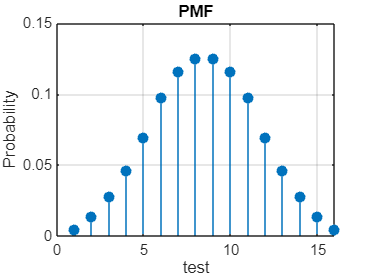

figure;
stem(sums, probabilities, 'filled');
title('PMF');
xlabel('test');
ylabel('Probability');
grid on;

3) Opskriv og tegn cdf'en Fx(x) for X.

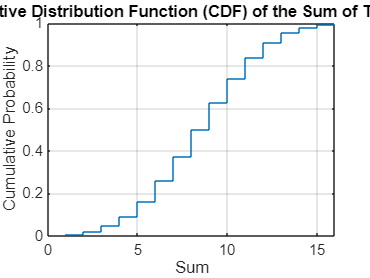

% Calculate the CDF from the PMF
cdf = cumsum(probabilities);
% Plot the CDF
figure;
stairs(sums, cdf);
title('Cumulative Distribution Function (CDF) of the Sum of Three Dice');
xlabel('Sum');
ylabel('Cumulative Probability');
grid on;

4) Hvad er sandsynligheden for at få 8?

prob8 = probabilities(8)

prob8 = 0.1250

5) Hvad er sandsynligheden for at få mindst 12?

least12 = 1-cdf(12)

least12 = 0.0926

6) Hvad er sandsynligheden for at få mindst 9 og højst 15?

cdf

cdf =     0.0046    0.0185    0.0463    0.0926    0.1620    0.2593    0.3750    0.5000    0.6250    0.7407    0.8380    0.9074    0.9537    0.9815    0.9954    1.0000


1-cdf(9)-(1-cdf(15))

ans = 0.3704

7) Hvad er sandsynligheden for at få færre end 4 eller flere end 16?

8) Hvad er det gennemsnitlige antal, man kan forvente at slå?

9) Hvad er variansen og standard afvigelsen af antallet?

10) Hvad er sandsynligheden for at antallet ligger inden for hhv. 1, 2 og 3 standard afvigelser fra middelværdien (dvs. 휇휇푋푋−휎휎푋푋≤푋푋 ≤휇휇푋푋+휎휎푋푋 , hhv. ±2휎휎푋푋 og ±3휎휎푋푋)?   

11) Hvis den første terning er en 6’er, hvad er så sandsynligheden for at den samlede sum for de tre slag er mindst 12?

12) Lav et Matlab program, der simulerer spillet og lav simuleringer af spørgmål 1) –   11) (spring evt. 3) over). 

13)Terningen skiftes ud med en snyde-terning, hvor sandsynligheden for at slå en 6’er er dobbelt så stor, som de øvrige slag. Modificer Matlab-programmet og gentag spg. 12) med snyde-terningen.